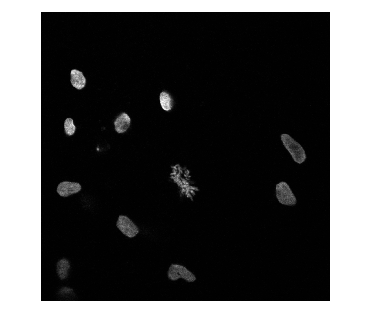

I_blue = imread("Chromosomes-blue.tif") ;
figure ; imshow(I_blue)

**FFT **low pass filter :

F = fftshift(fft2(I_blue));
Fb = F ;

cote = 100 ;
x = size(F, 1) /2;
y = size(F, 2) /2;

for i = 1:size(F, 1)
    for j= 1:size(F, 2)
        if i > x+cote || i < x-cote || j > y+cote || j< y-cote
            Fb(i,j) = 0;
        end
    end
end

rI = ifft2(ifftshift(Fb));

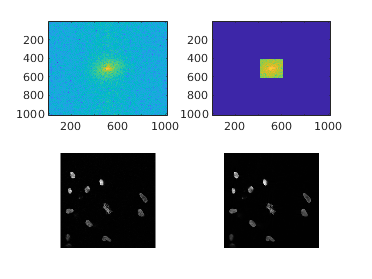

figure ;
subplot(2,2,1); imagesc(log(1+abs(F)));
subplot(2,2,2); imagesc(log(1+abs(Fb)));
subplot(2,2,3); imshow(I_blue);
subplot(2,2,4); imshow(uint16(real(rI)));

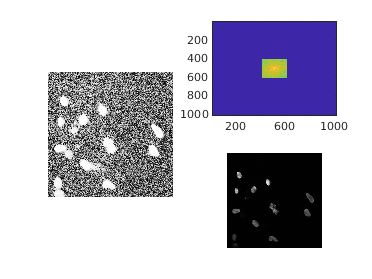

I_blue_eq = histeq(I_blue);
I_blue_eq_med = medfilt2(I_blue_eq, [30 30]);
subplot(1,2,1); imshow(I_blue_eq);

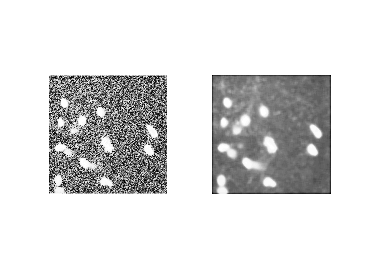

subplot(1,2,2); imshow(I_blue_eq_med);

**Threshold ** : method 1 with histogram equalization + median filter + manual threshold.

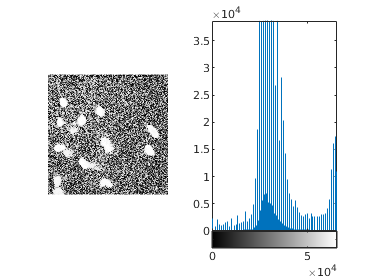

imhist(I_blue_eq_med)

I_blue_threshold1 = I_blue_eq_med ;
I_blue_threshold1(I_blue_threshold1 > 6.2*10^4) = 2^16 ;
I_blue_threshold1(I_blue_threshold1 <= 6.2*10^4) = 0 ;

**Threshold** : method 2 only manual threshold.

I_blue_threshold2 = I_blue;
I_blue_threshold2(I_blue_threshold2 > 5000) = 2^16 ;
I_blue_threshold2(I_blue_threshold2 <= 5000) = 0 ;

**Threshold** : method 3 Otsu.

[T,EM] = graythresh(I_blue_eq_med);
Iotsu = I_blue_eq_med; 
Iotsu(Iotsu>T*(2^16 -1)) = 2^16 -1;
Iotsu(Iotsu<=T*(2^16 -1)) = 0;
Iotsu_blue = logical(Iotsu);

**Comparisons :**

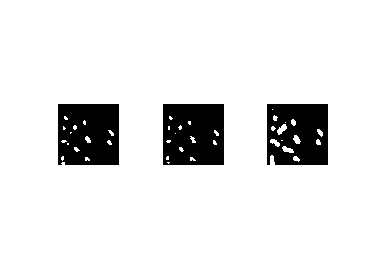

figure ;
subplot(1,3,1); imshow(logical(I_blue_threshold1));
subplot(1,3,2); imshow(logical(I_blue_threshold2));
subplot(1,3,3); imshow(logical(Iotsu_blue));

**Watershed** : detect cells positions.

map = bwdist(I_blue_threshold1);
L = watershed(map);
disp = labeloverlay(I_blue, L);
zones = max(unique(L));

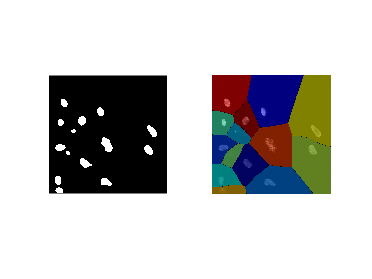

figure ;
subplot(1,2,1); imshow(logical(I_blue_threshold1));
subplot(1,2,2); imshow(disp);

**Crop** the cells from the image:

cells_blue = cell(zones, 1) ;
coord = zeros(2,2,zones) ;

for z=1:zones  
    [r1, c1] = find(L==z);
    wsregion = zeros(max(r1)-min(r1)+1, max(c1)-min(c1)+1);
    for i=min(r1):max(r1)
        for j=min(c1):max(c1)
            if L(i,j) == z && I_blue_threshold1(i,j)==2^16-1
                wsregion(i-min(r1)+1,j-min(c1)+1) = 1;
            else 
                wsregion(i-min(r1)+1,j-min(c1)+1) = 0;
            end
        end
    end
    wsregion = logical(wsregion);
    [r2, c2] = find(wsregion==1);
    % attention au changement de base / d'indice avec la matrice wsregion (+min(r1)-1 ; +min(c1)-1) :
    coord(:, :, z) = [min(r2)+min(r1)-1 max(r2)+min(r1)-1 ; min(c2)+min(c1)-1 max(c2)+min(c1)-1];
    wsregion = wsregion(min(r2):max(r2), min(c2):max(c2)) ;
    cells_blue{z} = wsregion ;
    display(z)
    clear r1 r2 c1 c2 ;
end

z = uint8
1

z = uint8
2

z = uint8
3

z = uint8
4

z = uint8
5

z = uint8
6

z = uint8
7

z = uint8
8

z = uint8
9

z = uint8
10

z = uint8
11

z = uint8
12

z = uint8
13

z = uint8
14

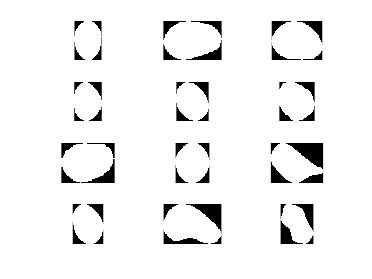

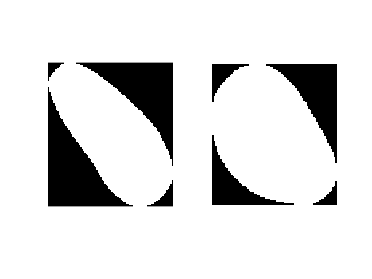

% Plot the cells from blue image
figure ;
for plotId=1:double(zones)
    subplot(2, 7, plotId); 
    imshow(cells_blue{plotId}) ;
end

I_green treatment :

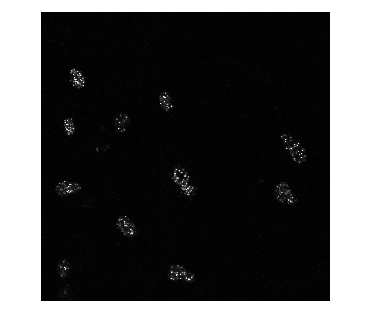

I_green = imread("Chromosomes-green.tif") ;
figure ; imshow(I_green) ;

% imhist(I_green)

**Crop** I_green according to regions extracted from I_blue

cells_green = cell(zones, 1);
for z=1:size(coord,3)
    xmin = coord(1,1,z);
    xmax = coord(1,2,z);
    ymin = coord(2,1,z);
    ymax = coord(2,2,z);
    cells_green{z} = I_green(xmin:xmax, ymin:ymax);
    clear xmin xmax ymin ymax
end

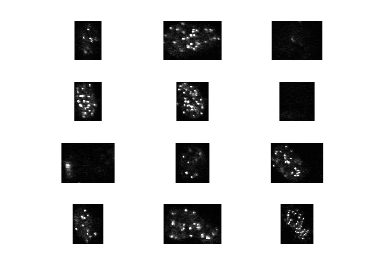

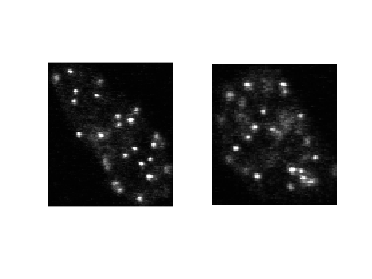

% Plot the cells from green image
figure ;
for plotId=1:double(zones)
    subplot(2, 7, plotId); 
    imshow(cells_green{plotId}) ;
end

**Otsu** on each cropped cell of I_green :

new_cells_green = cell(zones,1);
for c=1:zones
    I = cells_green{c};
    [T, ~]=graythresh(I);
    I(I>T*(2^16 -1)) = 2^16 -1;
    I(I<=T*(2^16 -1)) = 0;
    new_cells_green{c} = logical(I);
    clear I T
end

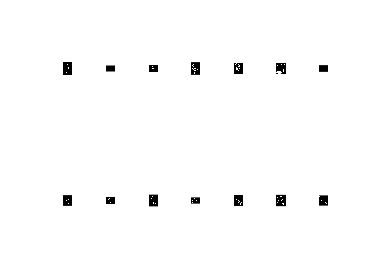

% Plot the thresholded cells from green image
figure ;
for plotId=1:double(zones)
    subplot(2, 7, plotId); 
    imshow(new_cells_green{plotId}) ;
end